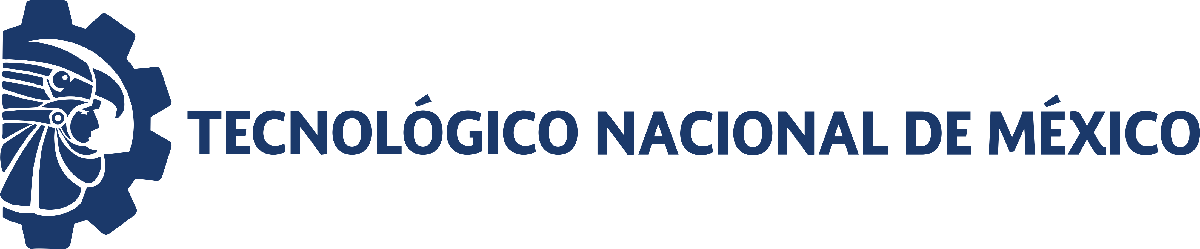                                 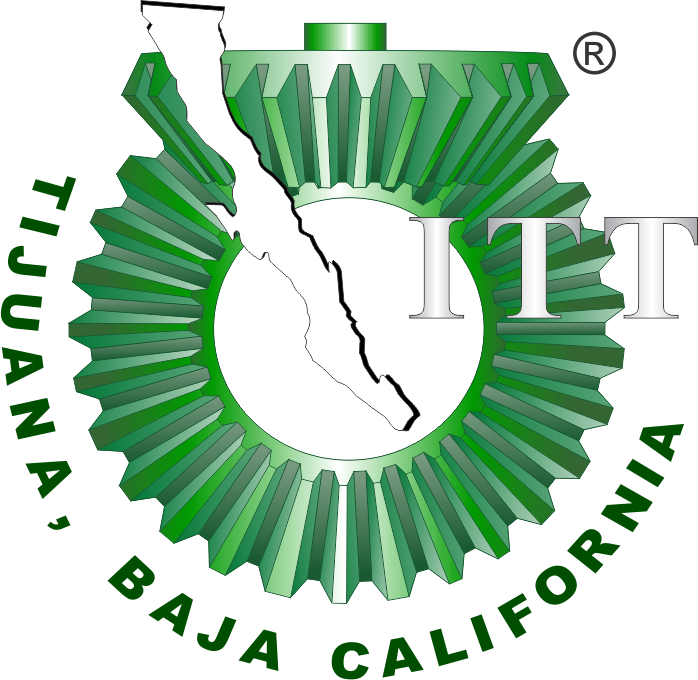

# Práctica dos: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

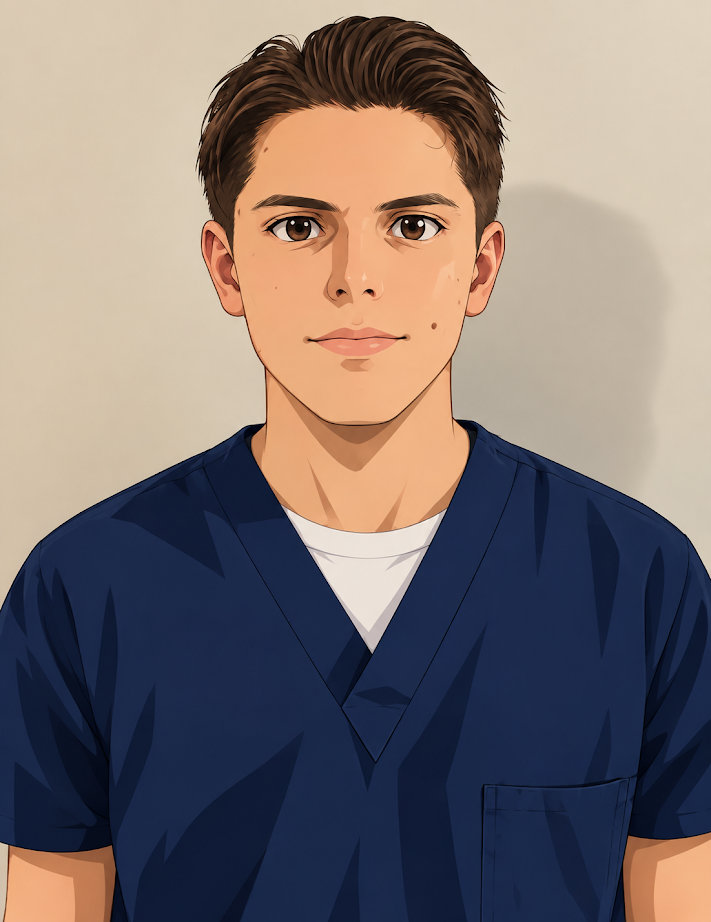

Nombre del alumno: Diego Macias Armenta

Número de control: 23212212

Correo institucional: **l23212212@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Practica2')
close_system('Practica2/Scope',0);
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('Practica2.slx',parameters);
t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data,x.Pa,t,'previous');
writematrix(Pa,'signal.xlsx')

## Respuesta de pacientes Normotenso, Hipotenso e Hipertenso

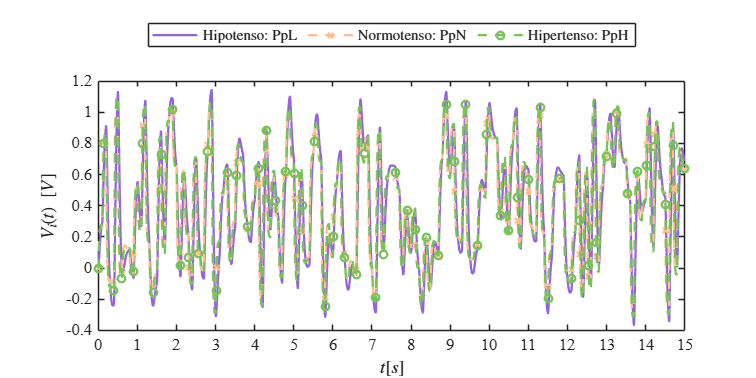

plotsignals(x.t, x.PpL, x.PpN, x.PpH, 'Normotenso', {'Hipotenso: PpL', 'Normotenso: PpN', 'Hipertenso: PpH'});

## Respuesta del paciente Hipotenso

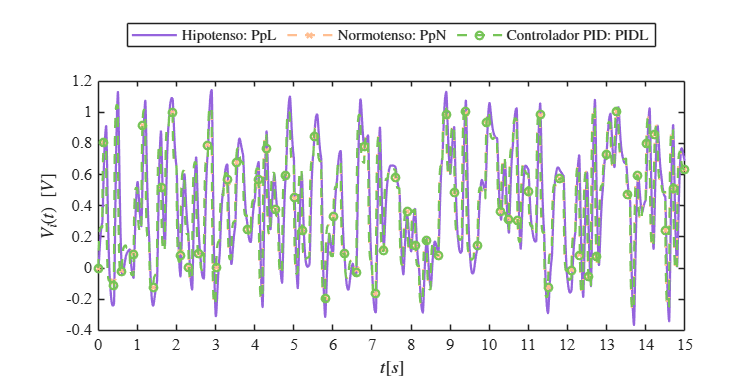

plotsignals(x.t, x.PpL, x.PpN, x.PIDL, 'Hipotenso', {'Hipotenso: PpL', 'Normotenso: PpN', 'Controlador PID: PIDL'});

## Respuesta del paciente Hipertenso

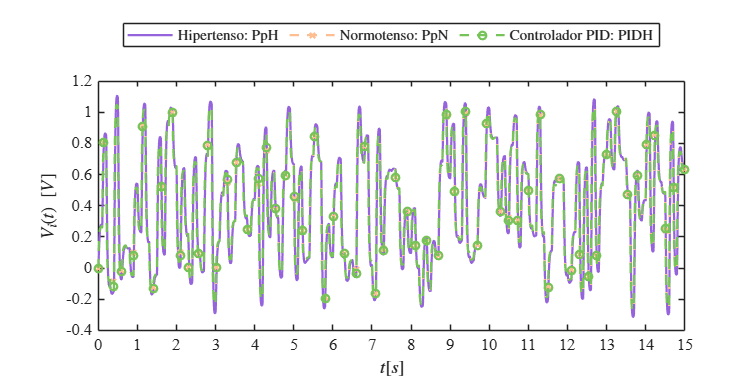

plotsignals(x.t, x.PpH, x.PpN, x.PIDH, 'Hipertenso', {'Hipertenso: PpH', 'Normotenso: PpN', 'Controlador PID: PIDH'});

## Modelo de EDOs

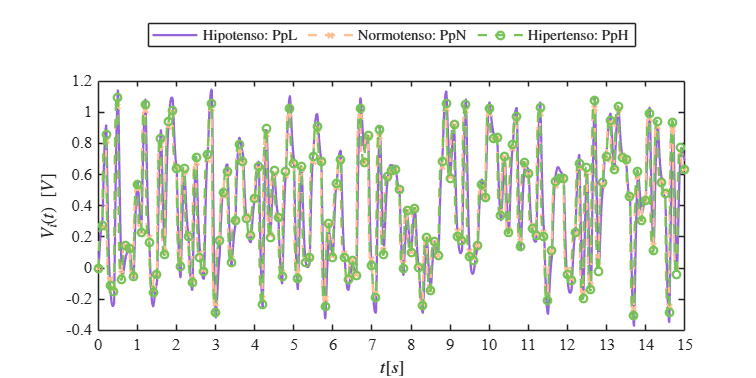

par_hipo = [0.010, 0.001, 1.000, 3.500]; % [Z,L,R,C]
par_normo = [0.010, 0.001, 1.000, 1.500];
par_hiper = [0.010, 0.001, 1.000, 1.000];
PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t,PpL,PpN,PpH,'Individuos',{'Hipotenso: PpL', 'Normotenso: PpN', 'Hipertenso: PpH'})


function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4);
    dt = t(2);
    n = round(t(end)/dt);
    
    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;

    for i = 1:n
        FL(i+1) = FL(i) + (-(1/L)*Pp(i) + (1/L)*Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C)*FL(i) - (1/(Z*C)+1/(R*C))*Pp(i) + 1/(Z*C)*Pa(i))*dt;
    end
end

## Función: Respuestas de la simulación


function plotsignals(t, PpN, PpHipo, PpHiper, signal, labels)

if isa(t, 'timeseries')
    t = t.Time;
end

if isa(PpN, 'timeseries')
    PpN = PpN.Data;
end

if isa(PpHipo, 'timeseries')
    PpHipo = PpHipo.Data;
end

if isa(PpHiper, 'timeseries')
    PpHiper = PpHiper.Data;
end

figure('Color','w');
set(gcf,'Units','inches','Position',[1,1,7,3.5]);
set(gca,'FontName','Times New Roman','FontSize',11);

hold on;
grid off;
box on;

clr1 = [149,100,221]/255;
clr2 = [255,190,145]/255;
clr3 = [118,196,87]/255;

colororder([clr1; clr2; clr3]);

plot(t, PpN, '-', t, PpHipo, '--x', t, PpHiper, '--o', 'LineWidth',1.5, 'MarkerSize',5, 'MarkerIndices',1:100:length(t));

L = legend(labels);

set(L,'Interpreter','latex','Location','northoutside','Orientation','horizontal');

xlabel('$t[s]$','Interpreter','latex');
ylabel('$V_i(t)\ [V]$','Interpreter','latex');

xlim([0 15]);
xticks(0:1:15);
ylim([-0.4 1.2]);
yticks(-0.4:0.2:1.2);

exportgraphics(gcf,[signal '_matlab.pdf'], ...
    'ContentType','vector');
end
